clear;

%Problem Number 1
tower = imread( 'white-tower', 'png' );
imshow( tower )

%k-means segmentation
k = 10
clusters = random_centers( tower, k );

%Change the image into an array of RGBPoints
W = size(tower, 2);
H = size(tower, 1);
points(H, W) = RGBPoint( tower(H,W,1), tower(H,W,2), tower(H,W,3) );


for y = 1:H
    for x = 1:W
        points(y, x) = RGBPoint( tower(y,x,1), tower(y,x,2), tower(y,x,3) );
    end
end

%Clean up the environment
clear tower;

%Begin the while loop
iterate = true;
while( iterate )
    
%Find out which cluster each point is in and add that point to the working
%average of that cluster
cluster_amount = zeros(k, 1);
cluster_average = zeros(k, 3);
for y = 1:H
    for x = 1:W
        points(y, x) = points(y, x).find_cluster( clusters );
        c = points(y, x).getcluster();
        cluster_average(c, 1) = (cluster_average(c, 1) * cluster_amount(c) + points(y,x).getr()) / (cluster_amount(c) + 1);
        cluster_average(c, 2) = (cluster_average(c, 2) * cluster_amount(c) + points(y,x).getg()) / (cluster_amount(c) + 1);
        cluster_average(c, 3) = (cluster_average(c, 3) * cluster_amount(c) + points(y,x).getb()) / (cluster_amount(c) + 1);
        cluster_amount( c ) = cluster_amount(c) + 1;
    end
end

%Create usable points out of the averages of each cluster
new_clusters(k) = RGBPoint();
for i = 1:k
    new_clusters(i) = RGBPoint( round( cluster_average(i, 1)),  round( cluster_average(i, 2)),  round( cluster_average(i, 3)) );
end

thresh = 150; %If RGB-Distance between two points are below this threshold, we consider them the same point.
[iterate, distance_array] = same_clusters( clusters, new_clusters, thresh );
iterate = ~iterate;
disp( "Distances between SSD of old clusters averages and new ones" );
disp( distance_array );

clusters = new_clusters;

end %End of while loop

clear distance_array cluster_amount cluster_average i iterate new_clusters thresh

disp( "These are the resulting clusters of the k-means algorithm." )
for i = 1:k
    clusters(i).show()
end

image = zeros( H, W, 3, 'uint8');
for y = 1:H
    for x = 1:W
        c = points(y, x).getcluster();
        image(y, x, 1) = uint8(clusters(c).getr());
        image(y, x, 2) = uint8(clusters(c).getg());
        image(y, x, 3) = uint8(clusters(c).getb());
    end
end

imshow( image );

clear k clusters points c clusters H i image k points W x y

%%This is problem 2
clear;

SLIC = imread( 'wt_slic.png', 'png' );
imshow( SLIC );
S = 50; %The distance between the beginning superpixel groups
W = size(SLIC, 2);
H = size(SLIC, 1);

%Change the image into the point form we used before
points(W, H) = RGBPoint( SLIC(H,W,1), SLIC(H,W,2), SLIC(H,W,3) );
for y = 1:H
    for x = 1:W
        points(x, y) = RGBPoint( SLIC(y,x,1), SLIC(y,x,2), SLIC(y,x,3) );
    end
end

clear SLIC

%Initialize the first centers of the superpixels to be every 50 pixels
num_super = ceil((H-S/2)/S) * ceil((W-S/2)/S)
super_pixels( num_super ) = Point();
new_super_pixels( num_super ) = FullPoint();
index = 1;
for y = S/2:S:H
    for x = S/2:S:W
        super_pixels(index) = Point(x, y);
        index = index + 1;
    end
end

clear index

%Check the gradient around each superpixel, and move to the minimum in a
%3x3 area
gradient = zeros(3, 3);
for i = 1:size(super_pixels, 2)
    %gradient 2,2 is where our pixel will be
    px = super_pixels(i).x;
    py = super_pixels(i).y;
    for x = -1:+1
        for y = -1:+1
            if px-x > 1 && px-x < W && py-y > 1 && py-y < H
                gradient(x+2, y+2) = ...
                    points(px-x-1, py).RGB_distance( points(px-x+1, py) ) + ...
                    points(px, py-y-1).RGB_distance( points(px, py-y+1));
            end
        end
    end
    %Gradient has been calculated for each point around the superpixel in a
    %3x3 window
    minx = 1;
    miny = 1;
    min_distance = gradient(1, 1);
    for x = 1:3
        for y = 1:3
            if gradient(x, y) < min_distance
                min_distance = gradient(x, y);
                minx = x;
                miny = y;
            end
        end
    end
    %minx and miny point to the least value in gradient
    new_super_pixels(i) = points( px+minx-2, py+miny-2).to_full_point(px+minx-2, py+miny-2).set_cluster(i);
end

clear gradient min_distance minx miny

super_pixels = new_super_pixels;
%All the superpixels are now set
%Run k-means in a 100 by 100 neighboorhood around each superpixel

iterate = true;
while( iterate )
    distance = Inf( W, H ); %accessed by a y,x pair. Stores distance to nearest superpixel.
    %Initialized to inf because initialliy, it's closest to no superpizel.
    
    for i = 1:num_super
        %We do this for each superpixel
        px = super_pixels(i).x;
        py = super_pixels(i).y;
        %We search in a 2S by 2S square for associated pixels
        for x = px-S:px+S
            for y = py-S:py+S
                %Make sure the pixel we're testing is within image
                %boundaries
                if x > 0 && x <= W && y > 0 && y <= H
                    dis = super_pixels(i).full_distance( points(x, y), x, y );
                    if dis < distance(x, y)
                        %Set the cluster and distance to the new center
                        distance(x, y) = dis;
                        points(x,y) = points(x,y).set_cluster(i);
                    end
                end
            end
        end
    end
    
    sup_amount = zeros(num_super, 1); %Holds the amount of pixels contained within each superpixel.
    sup_average = zeros(num_super, 5); %Holds the average of R, G, B, x, y for each superpixel
    
    for y = 1:H
        for x = 1:W
            %Find the averages of each superpixel so we can move them
            c = points(x, y).getcluster();
            sup_average(c, 1) = (sup_average(c, 1) * sup_amount(c) + points(x,y).getr()) / (sup_amount(c) + 1);
            sup_average(c, 2) = (sup_average(c, 2) * sup_amount(c) + points(x,y).getg()) / (sup_amount(c) + 1);
            sup_average(c, 3) = (sup_average(c, 3) * sup_amount(c) + points(x,y).getb()) / (sup_amount(c) + 1);
            sup_average(c, 4) = (sup_average(c, 4) * sup_amount(c) + x) / (sup_amount(c) + 1);
            sup_average(c, 5) = (sup_average(c, 5) * sup_amount(c) + y) / (sup_amount(c) + 1);
            sup_amount( c ) = sup_amount(c) + 1;
        end
    end
    
    %Create usable data out of the averages of each superpixel
    new_super_pixels( num_super ) = FullPoint();
    distance_arr = zeros( num_super, 1);
    for i = 1:num_super
        new_super_pixels(i) = FullPoint(...
            round( sup_average(i, 1)),...
            round( sup_average(i, 2)),...
            round( sup_average(i, 3)),...
            round( sup_average(i, 4)),...
            round( sup_average(i, 5))     );
        distance_arr( i ) = new_super_pixels(i).distance( super_pixels(i) );
    end
    
    %Determine whether or not to iterate
    thresh = 150;
    if max( distance_arr ) < thresh
        iterate = false;
    end
    
    %Set superpixels for the next iteration
    super_pixels = new_super_pixels;
    
end %End of k-means iteration

clear distance distance_arr min_distance new_super_pixels sup_amount sup_average

%super_pixels contains the final versions of super_pixels
%Each pixel in the points array has its cluster set accordingly

%Building the resulting image again
image = zeros( H, W, 3, 'uint8');
for y = 1:H
    for x = 1:W
        c = points(x, y).getcluster();
        image(y, x, 1) = uint8(super_pixels(c).getr());
        image(y, x, 2) = uint8(super_pixels(c).getg());
        image(y, x, 3) = uint8(super_pixels(c).getb());
    end
end

%add the black lines between each cluster boundary
for y = 3:H
    for x = 3:W
        if points(x,y).getcluster() ~= points(x-1,y).getcluster() ||...
            points(x,y).getcluster() ~= points(x,y-1).getcluster()
            %If a cluster has changed, make this pixel black
            image(y,x, 1) = uint8(0);
            image(y,x, 2) = uint8(0);
            image(y,x, 3) = uint8(0);
        end
    end
end
imshow( image );

disp( "SLIC Algorithm has finished" );


sky_test1.jpg


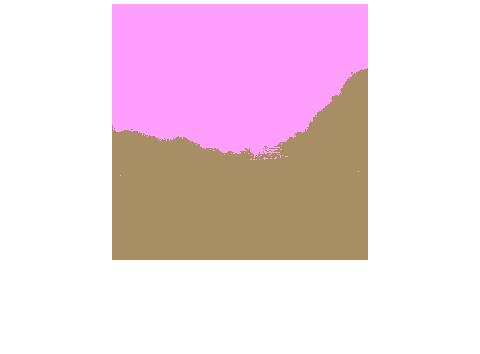

sky_test2.jpg


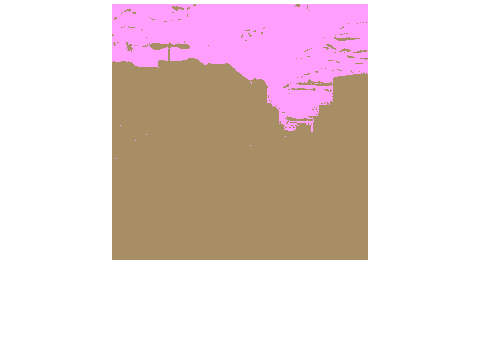

sky_test3.jpg


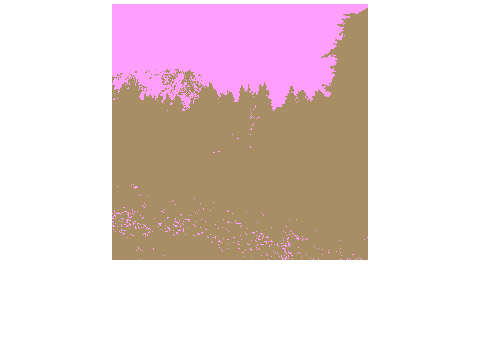

sky_test4.jpg


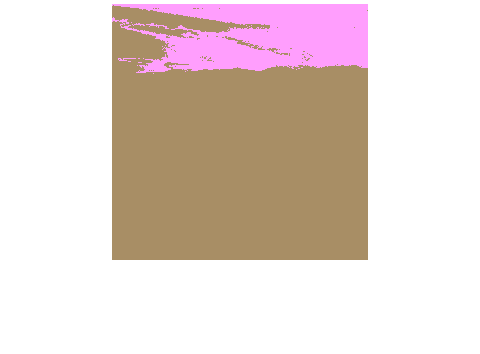

%%Problem Number 3
clear;

train_img = imread( "sky/sky_train.jpg" );
mask_img = imread( "sky/sky_mask.jpg");

mask = mask_img == 255;
num_sky_mask = max( uint8(mask), [], 3);
sky_mask = cat(3, num_sky_mask, num_sky_mask, num_sky_mask);
sky = bsxfun( @times, train_img, uint8(sky_mask));
points = reshape(sky, [], 3);
points(points(:, 3)== 0, :)= [];
[~, sky_words] = imsegkmeans( reshape(points,1,[],3), 10 );
%Sky words now contains the array of points that describe the sky

num_ground_mask = 1 - num_sky_mask;
ground_mask = cat(3, num_ground_mask, num_ground_mask, num_ground_mask);
ground = bsxfun( @times, train_img, uint8(ground_mask));
points = reshape(ground, [], 3);
points(points(:, 3)== 0, :)= [];
[~, ground_words] = imsegkmeans( reshape(points,1,[],3), 10 );
%Ground words now contains the array of points that describe the ground

clear ground ground_mask mask mask_img num_ground_mask num_sky_mask points sky sky_mask train_img

%ground_words and sky_words are now fully populated
test_paths = {'sky/sky_test1.jpg', 'sky/sky_test2.jpg', 'sky/sky_test3.jpg', 'sky/sky_test4.jpg'};
limit = length(test_paths);
for i = 1:limit
    disp( test_paths{i}(5:end) );
    image = sky_mask(sky_words, ground_words, test_paths{i} );
    imshow( image );
    figure;
    drawnow;
end